filename1 = 'GRADES 1.xlsx';
A = xlsread(filename1);

% Initialize an array to store the student averages
Student_Average1 = zeros(size(A, 1), 1);

% Loop through each row of the data
for i = 1:size(A, 1)
    row_sum = 0;
    num_valid_grades = 0;
    
    % Loop through each column of the current row
    for j = 1:size(A, 2)
        % Check if the value is not NaN (assuming NaN represents missing data)
        if ~isnan(A(i, j))
            row_sum = row_sum + A(i, j);

            num_valid_grades = num_valid_grades + 1;
        end
        
    end
    display(row_sum)

    
    % Calculate the average for the current student
    if num_valid_grades > 0
        Student_Average1(i) = row_sum / num_valid_grades;
    else
        % Handle the case where all grades for a student are missing
        Student_Average1(i) = NaN;
    end
end

row_sum = 376

row_sum = 384

row_sum = 319

row_sum = 375

row_sum = 402

row_sum = 436

row_sum = 416

row_sum = 315

row_sum = 441

row_sum = 342

row_sum = 348

row_sum = 302

row_sum = 303

row_sum = 298

row_sum = 279

row_sum = 327

row_sum = 309

row_sum = 271

row_sum = 309

row_sum = 259

row_sum = 191

row_sum = 187

row_sum = 283

row_sum = 324

row_sum = 319

row_sum = 329


% Display the student averages
display(Student_Average1);

Student_Average1 =    75.2000
   76.8000
   63.8000
   75.0000
   80.4000
   87.2000
   83.2000
   63.0000
   88.2000
   68.4000



% Now you can use your plotting functions with Student_Average1
c1=0

c1 = 0

c2=0

c2 = 0

c3=0

c3 = 0

for i = 1:size(A, 1)
    if (Student_Average1(i) >= 80) && (Student_Average1(i) <= 100)
       c1=c1+1
    
    elseif (Student_Average1(i) >= 60) && (Student_Average1(i) <= 70)
           c2=c2+1
    else
        c3=c3+1
    end
end 

c3 = 1

c3 = 2

c2 = 1

c3 = 3

c1 = 1

c1 = 2

c1 = 3

c2 = 2

c1 = 4

c2 = 3

c2 = 4

c2 = 5

c2 = 6

c3 = 4

c3 = 5

c2 = 7

c2 = 8

c3 = 6

c2 = 9

c3 = 7

c3 = 8

c3 = 9

c3 = 10

c2 = 10

c2 = 11

c2 = 12

% overall class performance
ranges = [c1 c2 c3]

ranges =      4    12    10


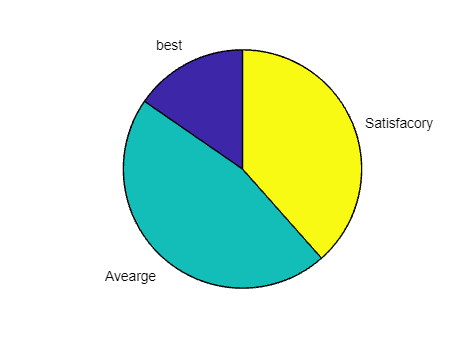

labels = {'best','Avearge','Satisfacory'};
pie(ranges,labels)